## Import Dataset

data_red = readtable('winequality-red.csv');

Error using readtable
Unable to find or open 'winequality-red.csv'. Check the path and filename or file permissions.

data_white = readtable('winequality-white.csv');

## Visualise Dataset

whos data_red
whos data_white
head(data_red)
head(data_white)

## Preprocessing Dataset

sum(ismissing(data_red))
sum(ismissing(data_white))

### Oversampling Red Wine Dataset

colMeans = varfun(@mean, data_red, 'OutputFormat', 'uniform')
numNewRows = height(data_white) - height(data_red)
extraData_red = array2table(repmat(colMeans, numNewRows, 1), 'VariableNames', data_red.Properties.VariableNames);

### Extract Features and Target

data_red = [data_red; extraData_red];
data_red.type = zeros(height(data_red), 1);
data_white.type = ones(height(data_white), 1);
data = [data_red; data_white];
head(data)
tail(data)
X = table2array(data(:, 1:11));
y = table2array(data(:, 13));

## Training the Neural Network

net = patternnet([5 5])     % 5 neurons in hidden layer
view(net)
%[net, tr] = train(net, X', y');

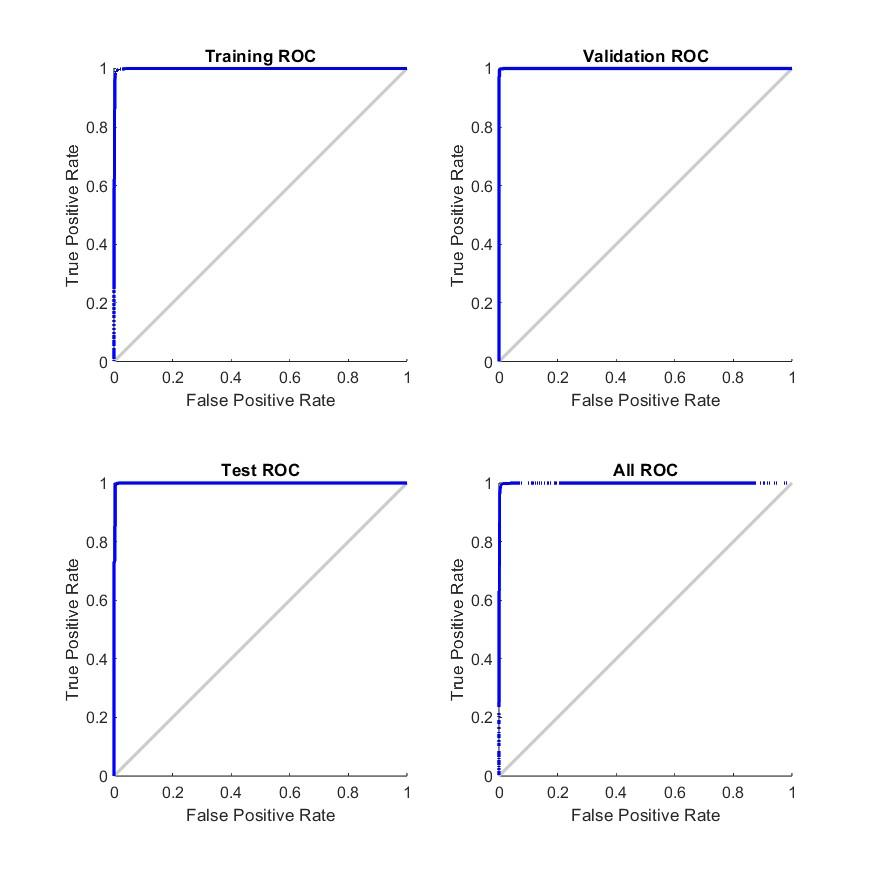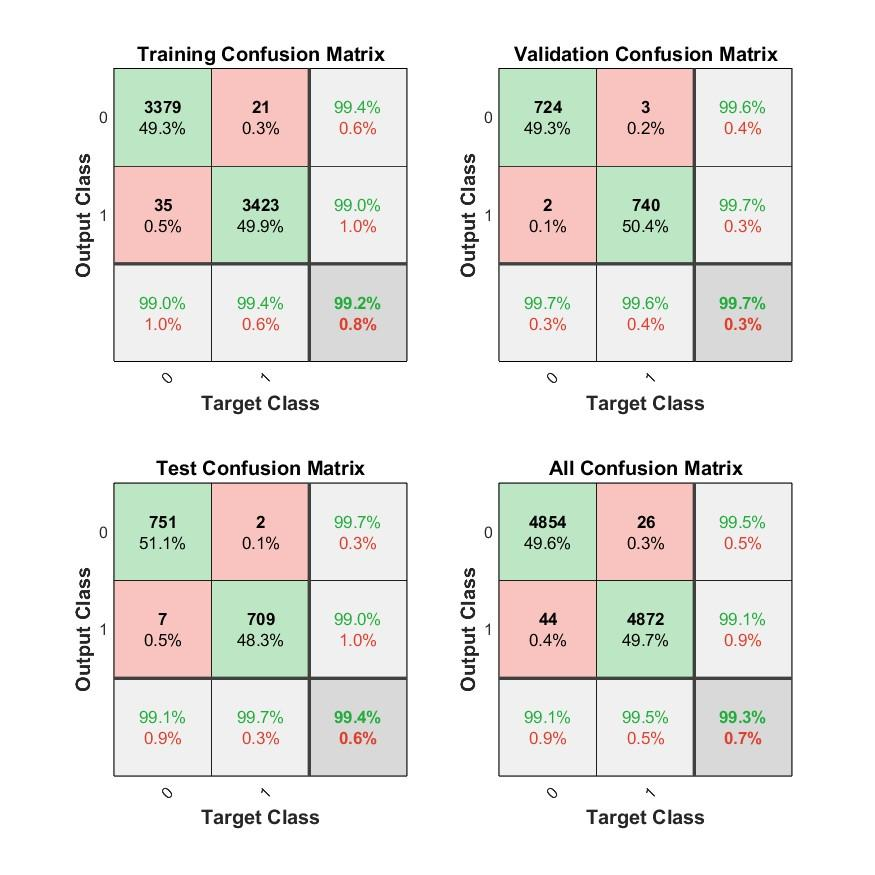

## Testing Neural Network Model

plotperform(tr)
%newData = table2array(data(1:10, 1:11))
%predictedLabels = sim(net, newData')